clear all;
load('g_mma_result.mat');
lambda0=3e-5;
multiplier = 1.1;
lambdaFinal = 0.2;
len = floor(log(lambdaFinal/lambda0)/log(multiplier))+1;
zMin = [10e-6 50e-6 100e-6 200e-6 500e-6 1000e-6];

h=waitbar(0,'Starting...');
%set(h,'doublebuffer','on');
for j = 1:length(zMin)
    for i = 1:len
        lambda(i) = lambda0*multiplier^(i-1);
        G(j,i) = geofactor(lambda(i),zMin(j));
        waitbar(((j-1)*len+i)/(len*length(zMin)),h,['Calculating...',num2str(((j-1)*len+i)/(len*length(zMin))*100,3),'%']);
    end
end
close(h);

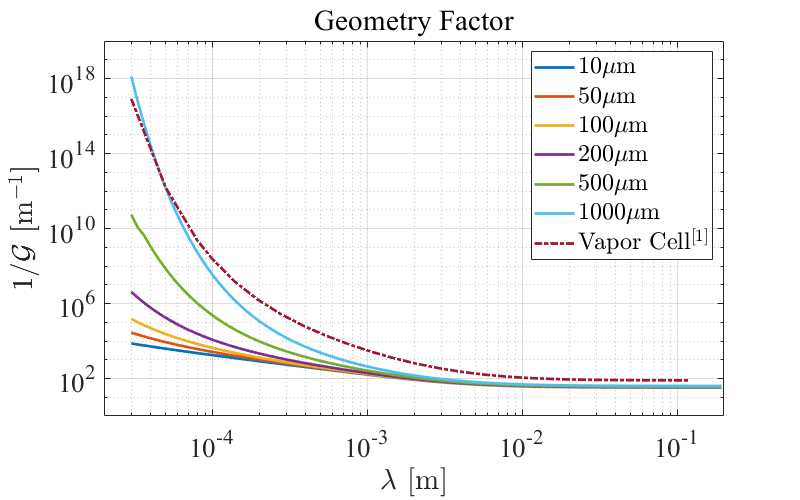

figure;
legend_string="";
for j=1:length(zMin)
    line = loglog(lambda,1./G(j,:));
    hold on;
    set(line,'linewidth',2);
    legend_string(j)=join([num2str(zMin(j)*1e6),'$\mu$m'],"");
end

yticks([1e2 1e6 1e10 1e14 1e18]);
xticks([1e-5 1e-4 1e-3 1e-2 1e-1]);xlim([2e-5 0.2]);
grid on;
set(gca,'fontsize',20,'fontname','times new roman','minorgridalpha',0.25);
set(gcf,'visible','on');
xlabel('$\lambda$ [m]','Interpreter',"latex");
ylabel('$1/\mathcal G$ $[\mathrm{m}^{-1}]$','Interpreter',"latex");


line=loglog(g_typein(:,1),1./g_typein(:,2));
legend_string(length(zMin)+1)='Vapor Cell$^{[1]}$';
set(line,'linewidth',2,"linestyle",'-.');


generate_legend(legend_string,'latex');
title("Geometry Factor");
set(gcf,'position',[500 400 800 500]);

function output = geofactor(lambda,zMin)
    fun = @(x,y,z) (1./(distance(x,y,z,0,0,0).*lambda) + 1./distance(x,y,z,0,0,0).^2).*...
    exp(-distance(x,y,z,0,0,0)./lambda).*z./distance(x,y,z,0,0,0);
    output = integral3(fun,-5e-3,5e-3,-5e-3,5e-3,zMin,zMin+0.02);
end


function output = distance(x1,y1,z1,x2,y2,z2)
    output = sqrt((x1-x2).^2+(y1-y2).^2+(z1-z2).^2);
end